# Get Galaxy Profiles

## Stellar constats


c = 299792.458; % Speed of light in vacuum (Km/s)
% The positive charge RMS anomality of nucleons
B_sigma = 0.0000000061576779354155376441072376072967;

% The Star parameters
A_Sigma_star = 0.000000000000004495594326077030347123131497606; % The abnormality of Star


sig_stars = 0.945*15000;
sig_H = 103;

% The Gas parameters
A_Sigma_H = 0.99e-10; % The electron-proton anomality of GAS

% Estimation parameters

resolution=200;
nloops = 14;


## Test of Milkyway data

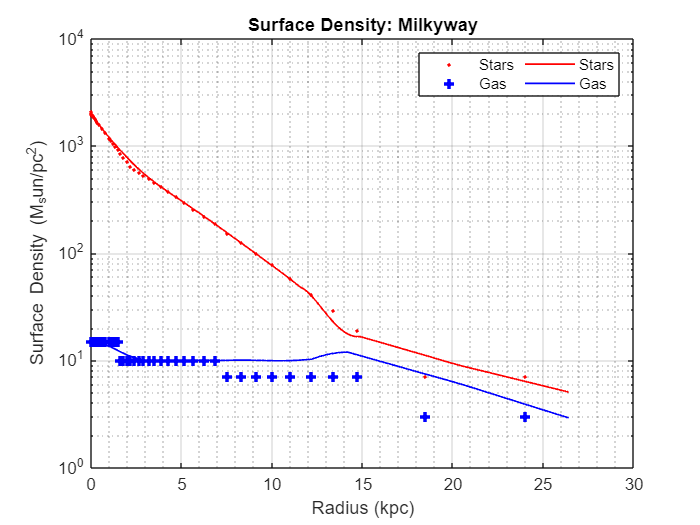

GalaxyName='Milkyway';

VelMassData = [
    0.0011	121.0000	18.2000	15	2000;
0.0015	108.0000	17.2000	15	2000;
0.0019	97.5000	16.0000	15	1999;
0.0025	93.5000	20.1000	15	1999;
0.0042	97.9000	30.0000	15	1997;
0.0054	98.2000	30.8000	15	1996;
0.0119	109.0000	42.5000	15	1989;
0.0155	112.0000	41.8000	15	1986;
0.0202	107.0000	37.1000	15	1981;
0.0262	99.6000	21.6000	15	1975;
0.0341	97.1000	13.8000	15	1967;
0.0443	104.0000	24.4000	15	1957;
0.0576	128.0000	33.5000	15	1944;
0.0748	137.0000	25.8000	15	1927;
0.0973	140.0000	33.7000	15	1906;
0.1260	145.0000	46.9000	15	1878;
0.1640	156.0000	60.6000	15	1843;
0.2140	214.0000	67.7000	15	1797;
0.2780	243.0000	37.6000	15	1739;
0.3610	249.0000	19.9000	15	1667;
0.4700	247.0000	11.7000	15	1576;
0.6100	240.0000	12.1000	15	1466;
0.7940	227.0000	13.3000	15	1331;
1.0200	216.0000	2.9800	15	1181;
1.1200	215.0000	2.7900	15	1122;
1.2300	213.0000	6.8300	15	1060;
1.3600	207.0000	7.8500	15	991;
1.4900	204.0000	6.0000	15	927;
1.6400	201.0000	4.7800	10	857;
1.8100	200.0000	3.4900	10	784;
1.9900	199.0000	5.9500	10	714;
2.1900	196.0000	7.2200	10	642;
2.4000	193.0000	6.0100	10	609;
2.6500	192.0000	4.3300	10	571;
2.9100	193.0000	5.2900	10	533;
3.2000	197.0000	7.7900	10	495;
3.5200	201.0000	7.9700	10	455;
3.8700	207.0000	10.1000	10	415;
4.2600	211.0000	8.4300	10	375;
4.6900	209.0000	6.8700	10	335;
5.1500	208.0000	8.3800	10	296;
5.6700	208.0000	12.0000	10	258;
6.2400	209.0000	16.6000	10	221;
6.8600	207.0000	13.0000	10	187;
7.5500	205.0000	9.6500	7	154;
8.3000	200.0000	15.8000	7	125;
9.1300	186.0000	24.2000	7	99;
10.0000	182.0000	35.2000	7	78;
11.0000	190.0000	49.6000	7	58;
12.2000	192.0000	49.9000	7	41;
13.4000	184.0000	54.5000	7	29;
14.7000	189.0000	64.7000	7	19;
18.5000	189.0000	59.9000	3	7;
24.0000	182.0000	70.6000	3	7;
];

figure(1)
[r_data,V_obs,V_err,R_kpc,r_model,V_model,SigmaS,SigmaG,MStars,Mgas] = SRotation_curves(VelMassData,GalaxyName);

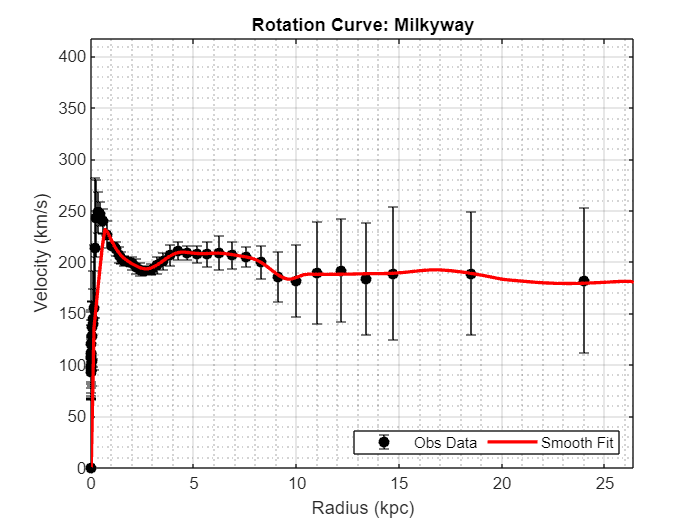


figure(2);
errorbar(r_data, V_obs, V_err, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Obs Data');
hold on;
plot(r_model, V_model, 'r-', 'LineWidth', 2, 'DisplayName', 'Smooth Fit');
xlabel('Radius (kpc)');
ylabel('Velocity (km/s)');
titles = append('Rotation Curve: ',GalaxyName);
title(titles);
legend('Location', 'southeast','NumColumns',2);
grid on;
grid minor;
xlim([0, max(r_model)]);
ylim([0, max(V_obs+3*V_err)]); % Enforce physical limits
hold off

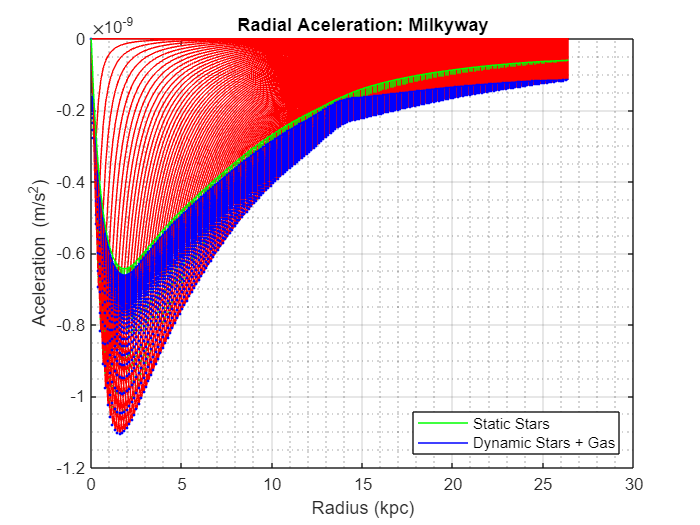

figure(3)
[V_tot,V_MOND,V_ele_G,V_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,MStars,Mgas,sig_stars,sig_H,resolution,0,GalaxyName);

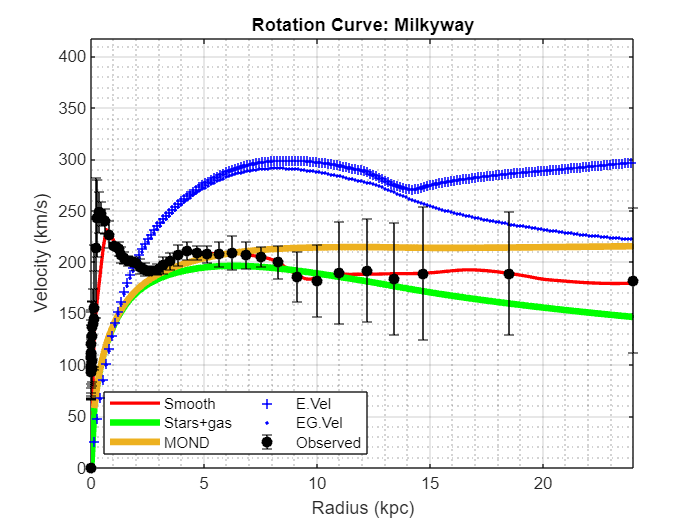

figure(4)
plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,V_ele,V_ele_G,GalaxyName);

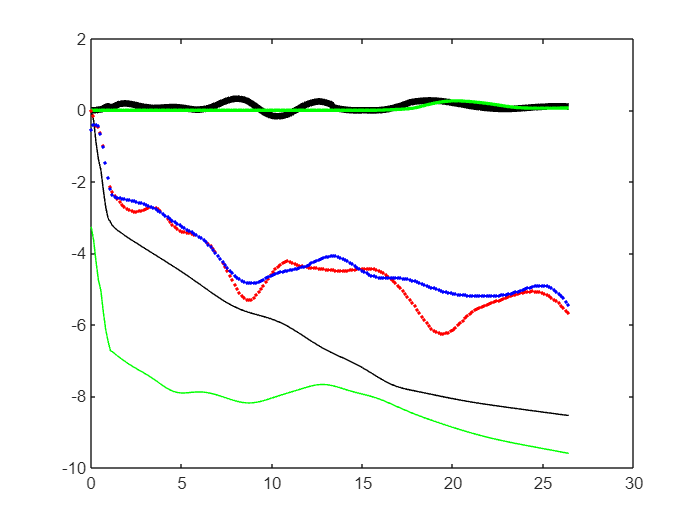

NSigma_S = MStars;
NSigma_H = Mgas;
NV_ele = V_ele;
testwhere=[];
for lps = 1:nloops
    ggain = 1.0-0.25*(mod(lps,3)>0) + 0.25*(mod(lps,3)==0);
    [Sigma_obs,Sigma_est,NSigma_S,NSigma_H,error,errorH,testwhere] = getNewDensities(r_model,V_model,NV_ele,NSigma_S,NSigma_H,0.35,2.0*(lps>1),ggain,testwhere);

    figure(5)
    plot(r_model,5*error,"k-",'LineWidth', 4)
    hold on
    plot(r_model,5*errorH,"g-",'LineWidth', 2)
    plot(r_model,log(NSigma_S/max(NSigma_S)),"k-")
    plot(r_model,log(NSigma_H/max(NSigma_S)),"g-")
    plot(r_model,log(Sigma_obs/max(Sigma_obs)),"r.")
    plot(r_model,log(Sigma_est/max(Sigma_obs)),"b.")
    hold off

    figure(6)
    [V_tot,V_MOND,NV_ele_G,NV_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,NSigma_S,NSigma_H,sig_stars,sig_H,resolution,lps,GalaxyName);

end

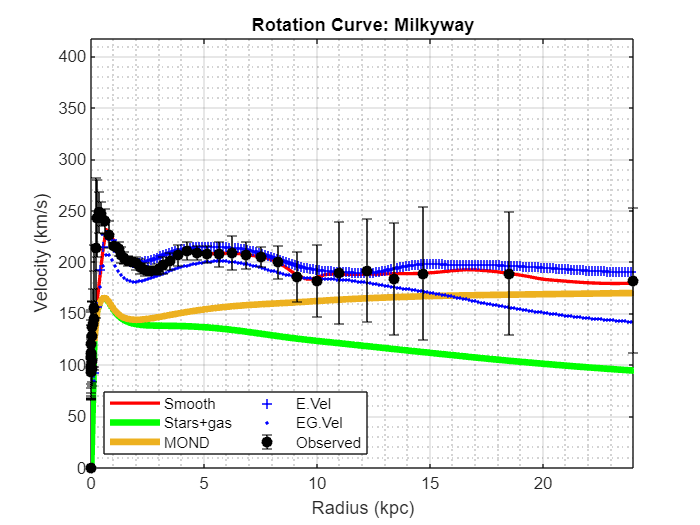

figure(7)
    plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,NV_ele,NV_ele_G,GalaxyName);

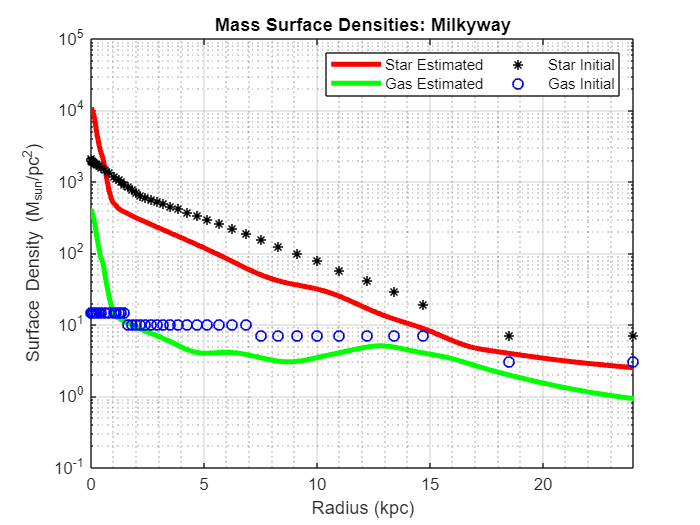

figure(8)
semilogy(r_model,NSigma_S,"r-", 'LineWidth', 3, 'DisplayName', 'Star Estimated')
hold on
semilogy(r_model,NSigma_H,"g-", 'LineWidth', 3, 'DisplayName', 'Gas Estimated')
semilogy(R_kpc,SigmaS,"k*", 'LineWidth', 1, 'DisplayName', 'Star Initial')
semilogy(R_kpc,SigmaG,"bo", 'LineWidth', 1, 'DisplayName', 'Gas Initial')
xlabel('Radius (kpc)');
ylabel('Surface Density (M_{sun}/pc^2)');
titles = append('Mass Surface Densities: ',GalaxyName);
title(titles);
legend('Location', 'northeast','NumColumns',2);
xlim([0, max(r_data)]);
grid on;
grid minor;
hold off


mascts = (1000^2)*2*pi*(r_model(3)-r_model(2));
totEstMASS = mascts*sum(MStars.*r_model)

totEstMASS = 1.0704e+11

totEstMASS2 = mascts*sum(NSigma_S.*r_model)

totEstMASS2 = 4.5283e+10

totEstMASS2/totEstMASS

ans = 0.4230

totEstGas = mascts*sum(NSigma_H.*r_model)

totEstGas = 5.5141e+09

TotGalMass = totEstMASS2+totEstGas

TotGalMass = 5.0797e+10

totObsEstRatioGas= sum(NSigma_H.*r_model)/sum(Mgas.*r_model)

totObsEstRatioGas = 0.3435

save("MilkyWayb_103_200.mat");